# Part 3

F = [ 0  1  0  2;
      0  0 -1 -1;
      -1 0  0  3;
      0  0  0  1];
F_loop = TranslationTransformation(F, -2, 4, 1)

F_loop =      0     1     0     0
     0     0    -1     3
    -1     0     0     4
     0     0     0     1


% F_R = RotationTransformation(F_T, "z", pi/4) ;
% F_R2 = RotationTransformation(F_R, "n", pi/6);

function T = TranslationTransformation(F, dx, dy, dz)
    Translate = [ 1 0 0 dx;
                  0 1 0 dy;
                  0 0 1 dz;
                  0 0 0 1];
    T = Translate * F;

end

function T = RotationTransformation(F, axis, angle)
    if ismember(axis, ["x", "n"])
        Rotation = [ 1      0          0      0;
                     0 cos(angle) -sin(angle) 0;
                     0 sin(angle) cos(angle)  0;
                     0      0         0       1];
    elseif ismember(axis, ["y", "o"])
        Rotation = [ cos(angle) 0 sin(angle) 0;
                     0          1     0      0;
                    -sin(angle) 0 cos(angle) 0;
                     0          0     0      1];
    elseif ismember(axis, ["z", "a"])
        Rotation = [ cos(angle) -sin(angle) 0 0;
                     sin(angle) cos(angle)  0 0;
                         0          0       1 0 ;
                         0          0       0 1];
    else
        Rotation = [0 0 0 0;
                    0 0 0 0;
                    0 0 0 0;
                    0 0 0 0;];
    end
    if ismember(axis, ["x", "y", "z"])
        T = Rotation * F;
    elseif ismember(axis, ["n", "o", "a"])
        T = F * Rotation;
    else
        T = [0 0 0 0;
             0 0 0 0;
             0 0 0 0;
             0 0 0 0;];
    end


end



# Part 4

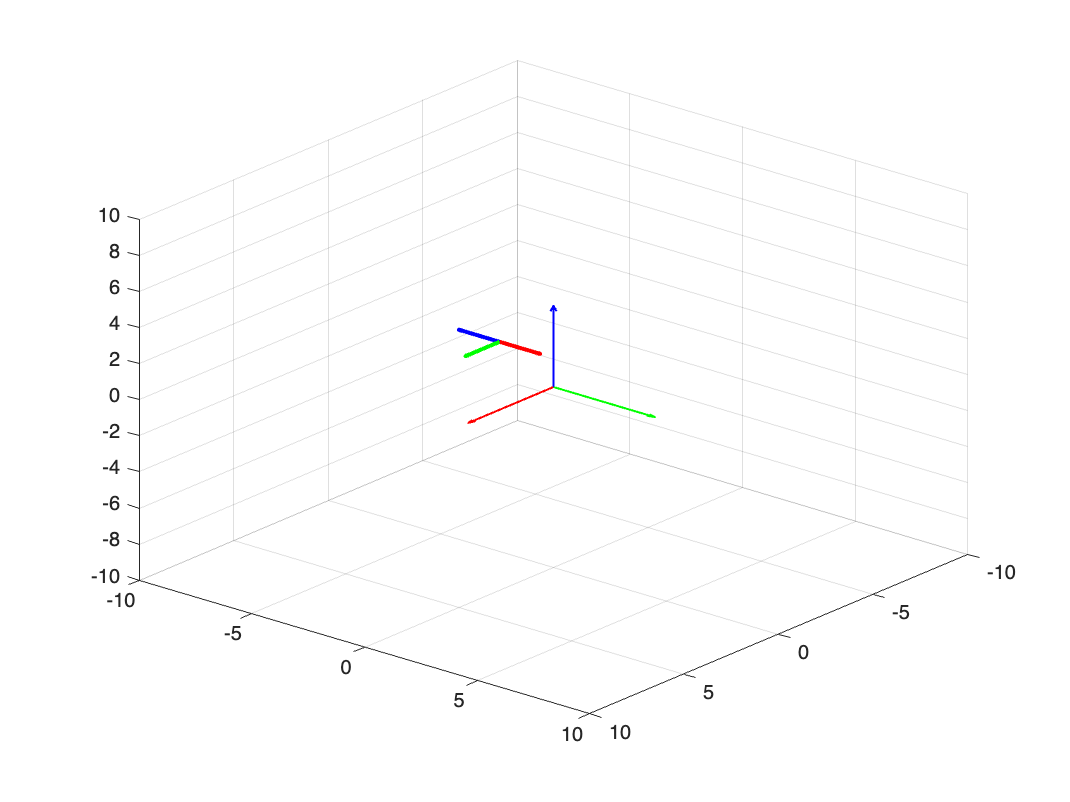

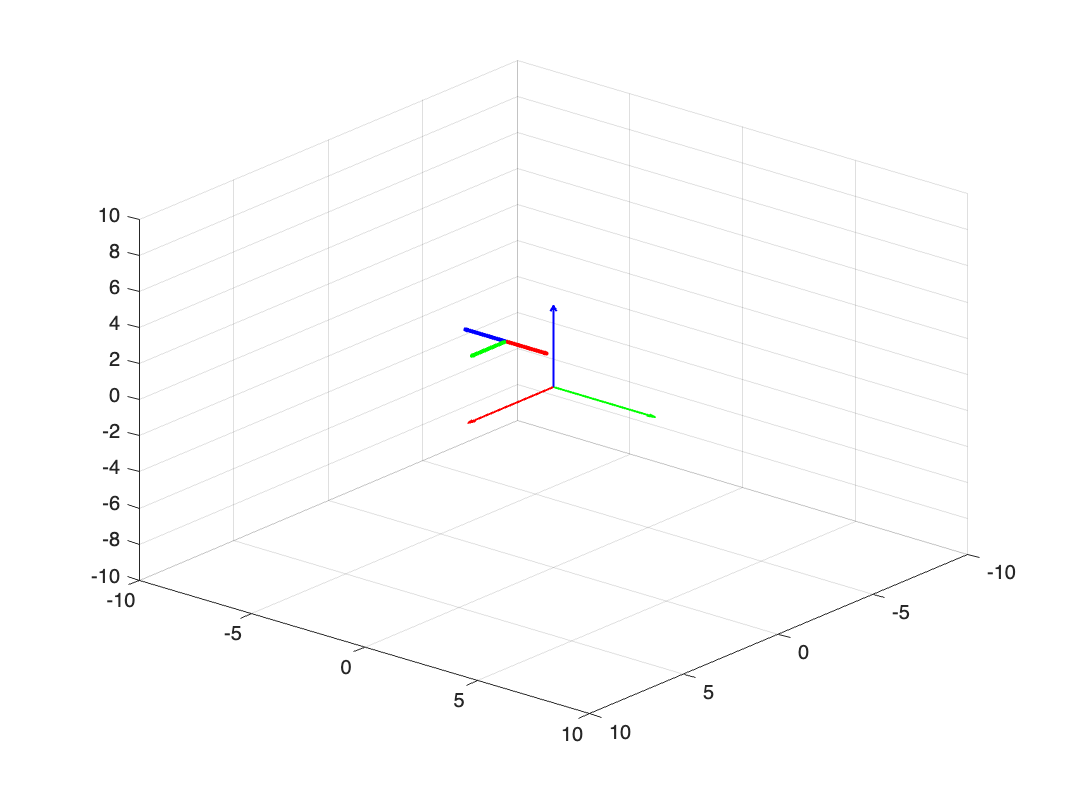

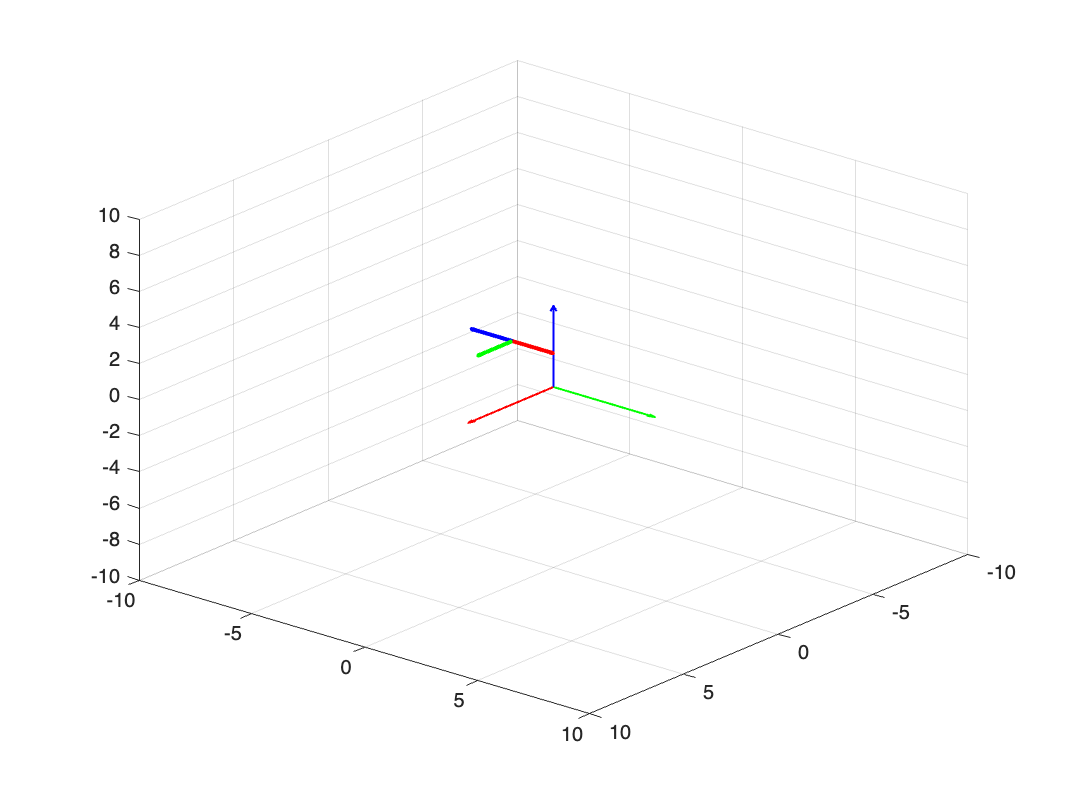

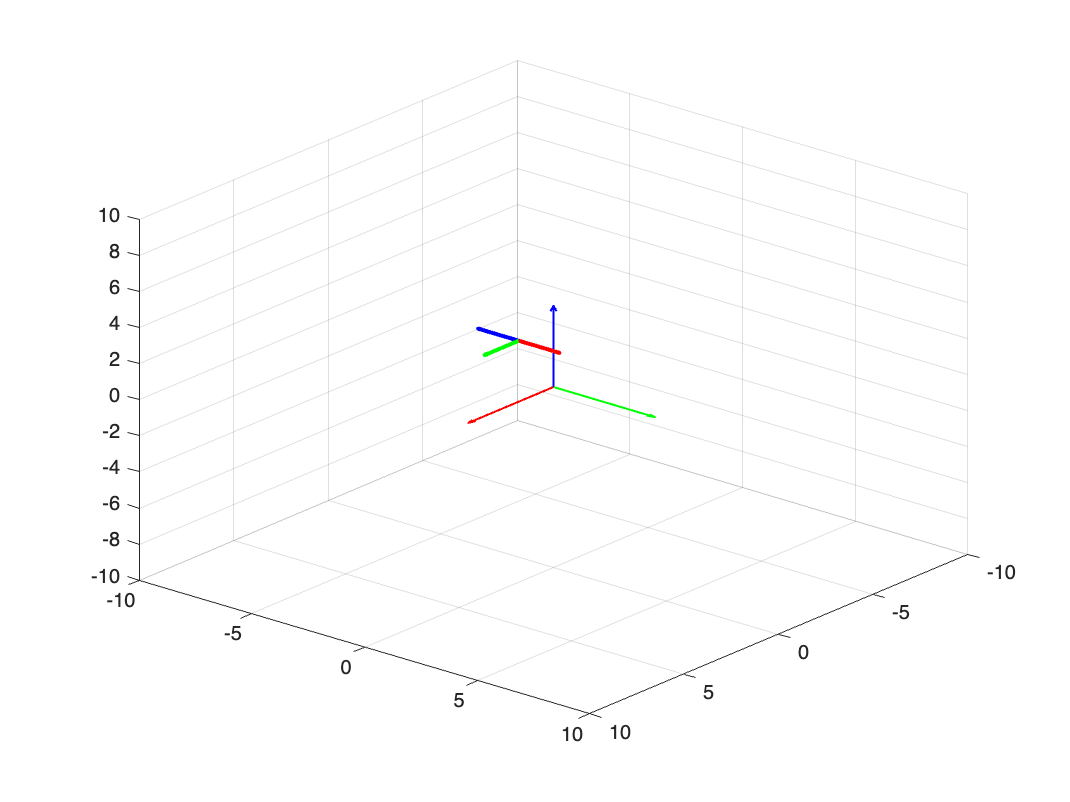

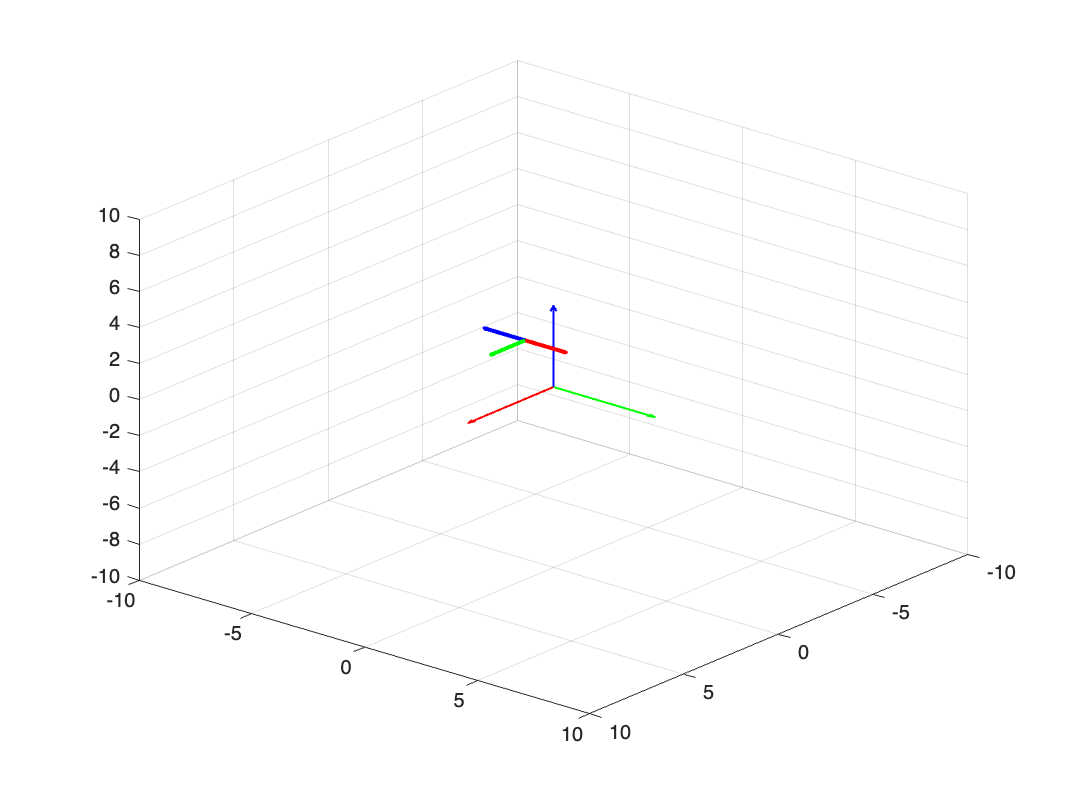

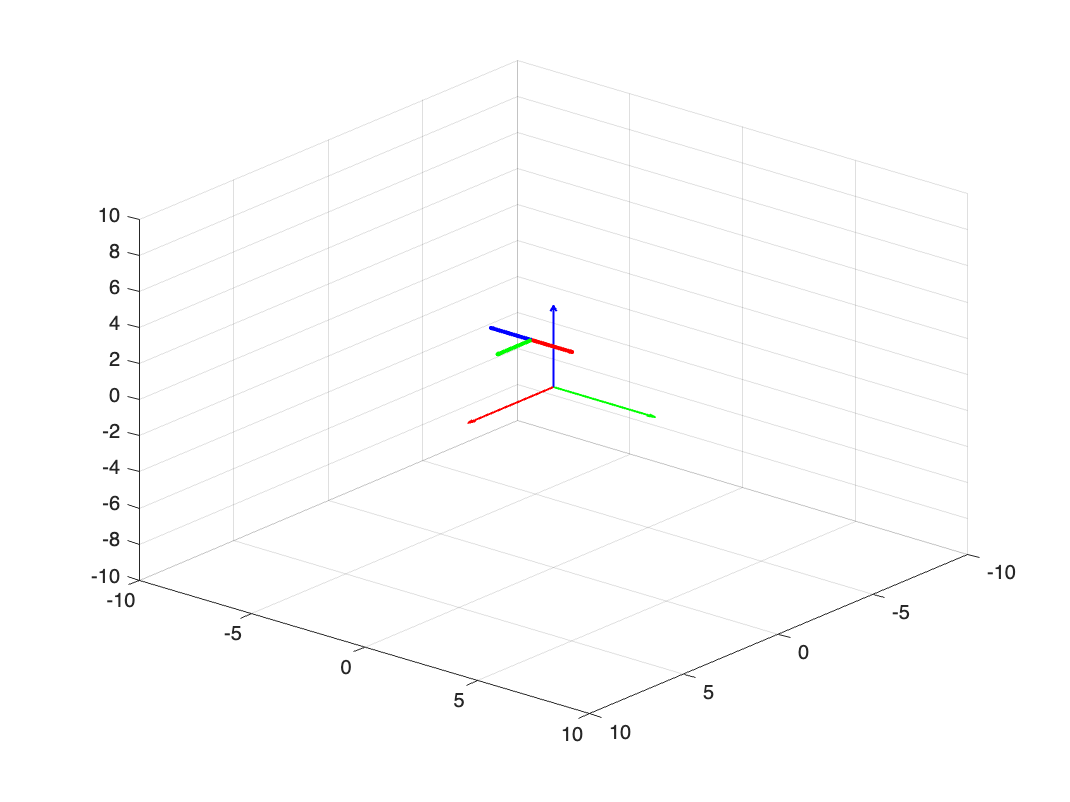

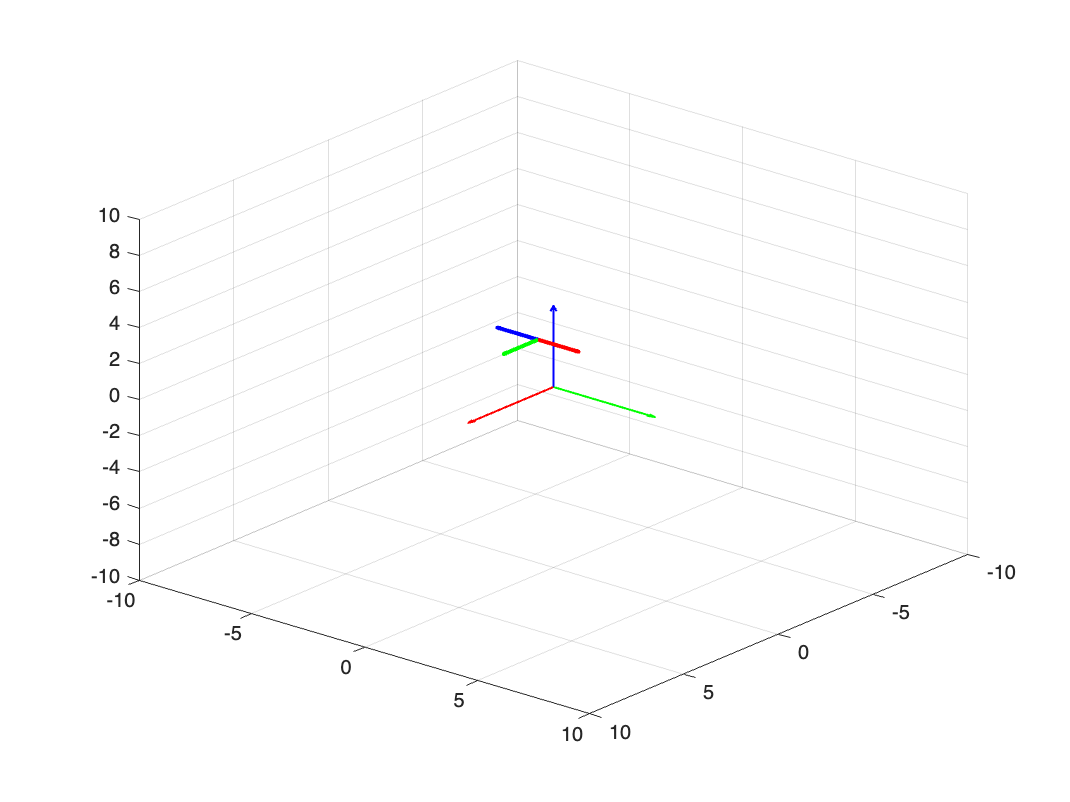

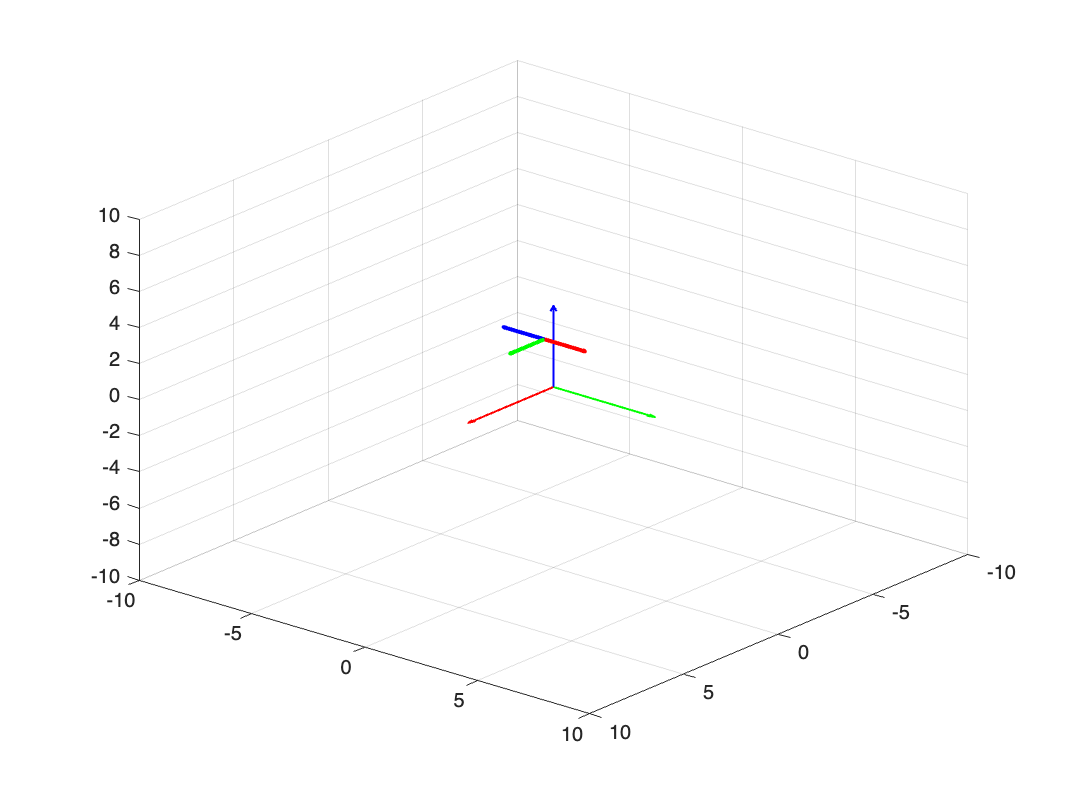

% figure
% grid on
% view([130,30])
% xlim([-10,10])
% ylim([-10,10])
% zlim([-10,10])


for i = 1:1:20
    figure
    grid on
    view([130,30])
    xlim([-10,10])
    ylim([-10,10])
    zlim([-10,10])
    hold on
    % X-Axis
    quiver3(0,0,0,5,0,0, LineWidth=1,Color= "red")
    % Y-Axis
    quiver3(0,0,0,0,5,0, LineWidth=1,Color= "green" )
    % Z-Axis
    quiver3(0,0,0,0,0,5, LineWidth=1,Color= "blue" )
    
    index = i * 1/20;
    F_loop = TranslationTransformation(F, -2*index, 4*index, 1*index);
    


    % X-Axis
    quiver3(F_loop(1,4),F_loop(2,4),F_loop(3,4),F_loop(1,1)*2,F_loop(1,2)*2,F_loop(3,2)*2, LineWidth=2,Color= "red" )
    % Y-Axis
    quiver3(F_loop(1,4),F_loop(2,4),F_loop(3,4),F_loop(1,2)*2,F_loop(2,2)*2,F_loop(3,2)*2, LineWidth=2,Color= "green" )
    % Z-Axis
    quiver3(F_loop(1,4),F_loop(2,4),F_loop(3,4),F_loop(1,3)*2,F_loop(2,3)*2,F_loop(3,3)*2, LineWidth=2,Color= "blue" )
    hold off
    
end